# 12:4:12:4

## Create data structure for each transitions type

ReFs = 20

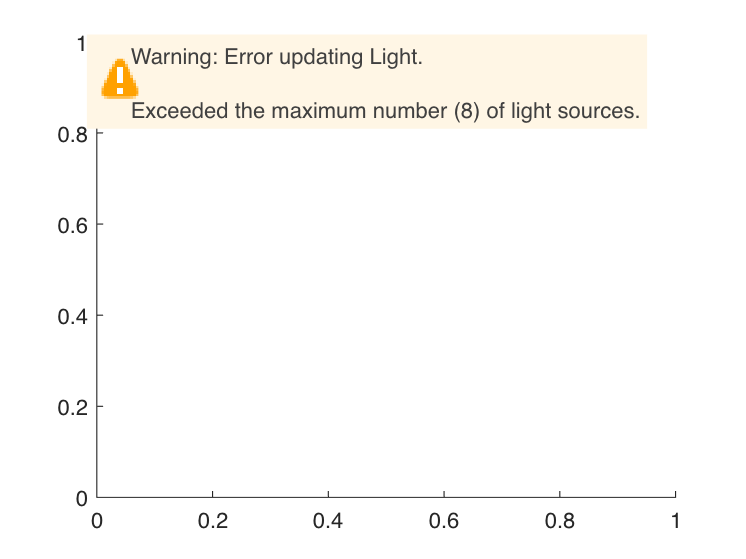

Unrecognized field name "regsumfft".

%prepare data in regular intervals of 20 seconds trimmed to light transitions
clearvars -except l24kg k

kg = l24kg;
ReFs = 20;
lightstart = 3;

onefish124idx = [64 65 66 67 68 69 70 71 72 74];
    for k = 1:length(onefish124idx)

        [phasekg(k).regtim, phasekg(k).regfreq, phasekg(k).regtemp, phasekg(k).regobw] = k_datatrimmean(l24kg(onefish124idx(k)), 1, ReFs);
       phasekg(k).lighttimes = k_lighttimes(l24kg(onefish124idx(k)),lightstart);
    end

## Divide data in transition types

## 12 to 4

### Expecting 12 hours of DARKness, get 4 hours

%experiment 1 - [64 66 67] 
exp1idx = [64 66 67];
starttim = 42;
hourwindow = 48;

    clear k;
    for k = 1:length(exp1idx)
        phasekgidx = find(onefish124idx == exp1idx(k)); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         twL4D(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         twL4D(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         twL4D(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 2 - [68 69 70]
exp2idx = [68 69 70];
starttim = 186;

    
    for k = k+1:1:k+length(exp2idx)
        phasekgidx = find(onefish124idx == exp2idx(k-length(exp1idx))); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
           twL4D(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         twL4D(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         twL4D(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 3 - [72 74]
exp3idx = [72 74];
starttim = 66;

    
    for k = k+1:1:k+length(exp3idx)
        phasekgidx = find(onefish124idx == exp3idx(k-(length(exp1idx)+length(exp2idx)))); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         twL4D(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         twL4D(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         twL4D(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

figure(444); clf; sgtitle('Expecting 12 hours of darkness and get 4'); hold on;
for k = 1:length(twL4D)
    ax(k) = subplot(length(twL4D), 1, k); hold on;
    for j = 1:length(twL4D(1).lighttimes)-1
        if mod(j, 2) == 1 %if idex is odd
           fill([twL4D(1).lighttimes(j) twL4D(1).lighttimes(j), twL4D(1).lighttimes(j+1) twL4D(1).lighttimes(j+1)], [-1 1 1 -1], [0.9 0.9 0.9]);
        end
    end
    plot(twL4D(k).xx, twL4D(k).regobw, '.');
    plot([twL4D(1).lighttimes' twL4D(1).lighttimes'], ylim, 'k-');

    
end
linkaxes(ax, 'x');

### Expecting 12 hours of LIGHT, get 4 hours

%experiment 1 - [64 66 67] 
exp1idx = [64 66 67];
starttim = 198;
hourwindow = 52;

    clear k;
    for k = 1:length(exp1idx)
        phasekgidx = find(onefish124idx == exp1idx(k)); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         twD4L(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         twD4L(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         twD4L(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 2 - [68 69 70]
exp2idx = [68 69 70];
starttim = 186;

    
    for k = k+1:1:k+length(exp2idx)
        phasekgidx = find(onefish124idx == exp2idx(k-length(exp1idx))); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
          twD4L(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         twD4L(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         twD4L(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 3 - [72 74]
exp3idx = [72 74];
starttim = 66;

    
    for k = k+1:1:k+length(exp3idx)
        phasekgidx = find(onefish124idx == exp3idx(k-(length(exp1idx)+length(exp2idx)))); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
          twD4L(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         twD4L(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         twD4L(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

figure(445); clf; sgtitle('Expecting 12 hours of Light and get 4'); hold on;
for k = 1:length(twD4L)
    ax(k) = subplot(length(twD4L), 1, k); hold on;
    for j = 1:length(twD4L(1).lighttimes)-1
        if mod(j, 2) == 0 %if idex is even
           fill([twD4L(1).lighttimes(j) twD4L(1).lighttimes(j), twD4L(1).lighttimes(j+1) twD4L(1).lighttimes(j+1)], [-1 1 1 -1], [0.9 0.9 0.9]);
        end
    end
    plot(twD4L(k).xx, twD4L(k).regobw, '.');
    plot([twD4L(1).lighttimes' twD4L(1).lighttimes'], ylim, 'k-');
    
end

linkaxes(ax, 'x');

## 4 to 12

### Expecting 4 hours of DARKness, get 12

%experiment 1 - [64 66 67] 
exp1idx = [64 66 67];
starttim = 114;
hourwindow = 48;

    clear k;
    for k = 1:length(exp1idx)
        phasekgidx = find(onefish124idx == exp1idx(k)); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         frL12D(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         frL12D(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         frL12D(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 2 - [68 69 70]
exp2idx = [68 69 70];
starttim = 258;

    
    for k = k+1:1:k+length(exp2idx)
        phasekgidx = find(onefish124idx == exp2idx(k-length(exp1idx))); 
    
           %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         frL12D(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         frL12D(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         frL12D(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 3 - [72 74]
exp3idx = [72 74];
starttim = 138;

    
    for k = k+1:1:k+length(exp3idx)
        phasekgidx = find(onefish124idx == exp3idx(k-(length(exp1idx)+length(exp2idx)))); 
    
           %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         frL12D(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         frL12D(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         frL12D(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

figure(446); clf; sgtitle('Expecting 4 hours of dark, get 12'); hold on;
for k = 1:length(frL12D)
    ax(k) = subplot(length(frL12D), 1, k); hold on;
    for j = 1:length(frL12D(1).lighttimes)-1
        if mod(j, 2) == 1 %if idex is odd
           fill([frL12D(1).lighttimes(j) frL12D(1).lighttimes(j), frL12D(1).lighttimes(j+1) frL12D(1).lighttimes(j+1)], [-1 1 1 -1], [0.9 0.9 0.9]);
        end
    end
    plot(frL12D(k).xx, frL12D(k).regobw, '.');
    plot([frL12D(1).lighttimes' frL12D(1).lighttimes'], ylim, 'k-');
    
end
linkaxes(ax, 'x');

### Expecting 4 hours of LIGHT, get 12

%experiment 1 - [64 66 67] 
exp1idx = [64 66 67];
starttim = 294;
hourwindow = 48;

    clear k;
    for k = 1:length(exp1idx)
        phasekgidx = find(onefish124idx == exp1idx(k)); 
       
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         frD12L(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         frD12L(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         frD12L(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 2 - [68 69 70]
exp2idx = [68 69 70];
starttim = 101;

    
    for k = k+1:1:k+length(exp2idx)
        phasekgidx = find(onefish124idx == exp2idx(k-length(exp1idx))); 
    
        %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         frD12L(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         frD12L(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         frD12L(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

%experiment 3 - [72 74]
exp3idx = [72 74];
starttim = 270;

    
    for k = k+1:1:k+length(exp3idx)
        phasekgidx = find(onefish124idx == exp3idx(k-(length(exp1idx)+length(exp2idx)))); 
    
         %indicies for time variable   
         xxidx = find(phasekg(phasekgidx).regtim/3600 >= starttim & phasekg(phasekgidx).regtim/3600 <= starttim + hourwindow);
         %indicies for light transition lines
         lightidx = find(phasekg(phasekgidx).lighttimes/3600 >= starttim & phasekg(phasekgidx).lighttimes/3600 <= starttim + hourwindow);
        
         frD12L(k).regobw = phasekg(phasekgidx).regobw(xxidx);
         frD12L(k).xx = phasekg(phasekgidx).regtim(xxidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
         frD12L(k).lighttimes = phasekg(phasekgidx).lighttimes(lightidx)/3600-phasekg(phasekgidx).regtim(xxidx(1))/3600;
    
    end

figure(447); clf; sgtitle('Expecting 4 hours of light, get 12'); hold on;
for k = 1:length(frD12L)
    ax(k) = subplot(length(frD12L), 1, k); hold on;
    for j = 1:length(frD12L(1).lighttimes)-1
        if mod(j, 2) == 0 %if idex is EVEN
           fill([frD12L(1).lighttimes(j) frD12L(1).lighttimes(j), frD12L(1).lighttimes(j+1) frD12L(1).lighttimes(j+1)], [-1 1 1 -1], [0.9 0.9 0.9]);
        end
    end
    plot(frD12L(k).xx, frD12L(k).regobw, '.');
    plot([frD12L(1).lighttimes' frD12L(1).lighttimes'], ylim, 'k-');
    
end
linkaxes(ax, 'x');


